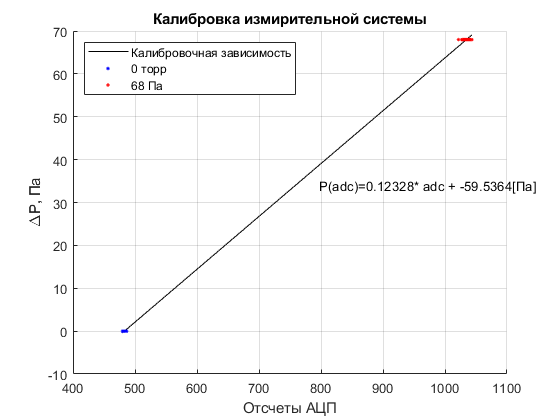

callib = load('jet/jet/2-experimentData/calib.dat');
callibr_zero = load("jet/jet/2-experimentData/calibzero.dat");
mm01 = load ("jet/jet/2-experimentData/01mm.dat");
mm11 = load("jet/jet/2-experimentData/11mm.dat");
mm21 = load("jet/jet/2-experimentData/21mm.dat");
mm31 = load("jet/jet/2-experimentData/31mm.dat");
mm41 = load("jet/jet/2-experimentData/41mm.dat");
mm51 = load("jet/jet/2-experimentData/51mm.dat");
mm61 = load("jet/jet/2-experimentData/61mm.dat");
mm71 = load("jet/jet/2-experimentData/71mm.dat");
adc_1 = callib (:, 2);
adc_2 = callibr_zero (:, 2);
p1 = ones(length(adc_1),1)*68;
p2 = ones(length(adc_2),1)*0;
Adc_c = [adc_1; adc_2];
P_c = [p1; p2];
c = polyfit(Adc_c, P_c, 1);
callibrFigure = figure ('Name','Калибровка', "NumberTitle","off");
hold all;
plot(Adc_c, polyval(c, Adc_c),'k-');
plot(adc_2, p2, 'b.');
plot(adc_1, p1, 'r.');
grid on;
xlabel('Отсчеты АЦП');
ylabel('\DeltaP, Па');
legend('Калибровочная зависимость','0 торр','68 Па', 'Location',"northwest");
title('Калибровка измирительной системы');
text(mean(Adc_c)*1.05, mean(P_c),['P(adc)=', num2str(c(1)), '* adc + ', num2str(c(2)), '[Па]']);
%%set(gcf, "Visible", "on")
dx = 0.25;
x = mm01(:, 1)'*0.25;
p01 = polyval(c , mm01(:,2));
p11 = polyval(c , mm11(:,2));
p21 = polyval(c , mm21(:,2));
p31 = polyval(c , mm31(:,2));
p41 = polyval(c , mm41(:,2));
p51 = polyval(c , mm51(:,2));
p61 = polyval(c , mm61(:,2));
p71 = polyval(c , mm71(:,2));
pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм';'71 мм'};
z = [1, 11, 21,31,41,51, 61, 71];
f2 = figure ('Name','Калибровка      ', "NumberTitle","off"); 
hold on;
grid on; 
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel('Расстояние вдоль сечения струи, мм');
ylabel('\DeltaP, Па');
for i = 1:size (pressure, 2)
    plot(x, pressure(:, i), "DisplayName", zNames{i});
end
legend('Location','northwest');
saveas(f2, 'pressure.png');

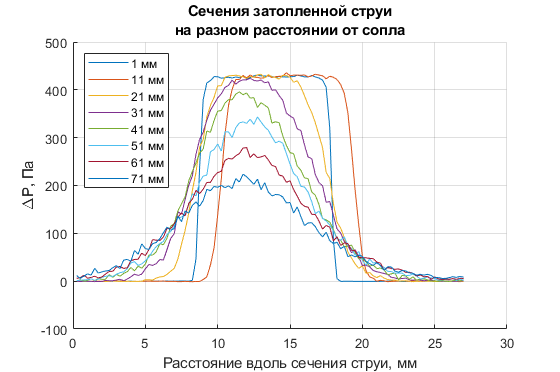

set(gcf, "Visible", "on");

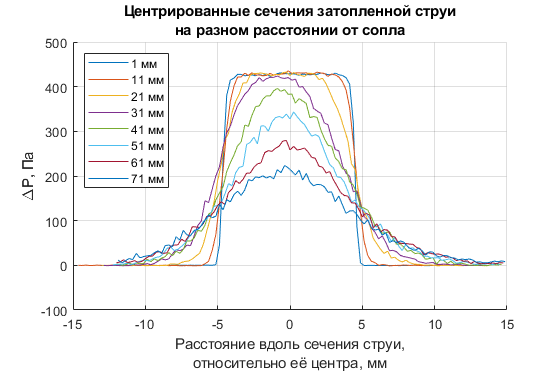

f3 = figure('Name','Калибровка      ', "NumberTitle","off");
hold on ;
grid on;
title({'Центрированные сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel({'Расстояние вдоль сечения струи,','относительно её центра, мм'});
ylabel('\DeltaP, Па');
xCentred = zeros(size(pressure));
offset = 50;
for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    center = left + (right - left)/2 ;
    xCentred(:, i) = x - center;
    plot(xCentred(:, i), pressure(:,i), 'DisplayName', zNames{i});
end
legend('Location','northwest');
saveas(f3, 'centered_pressure.png');
set(gcf, "Visible", "on");
hold off;

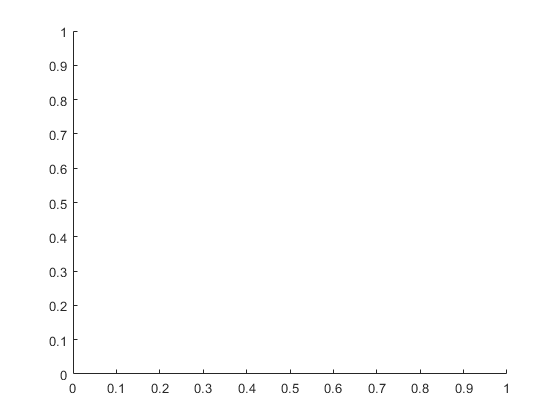

U_01 = -sqrt(2*abs(p01-mean(adc_2))/1.2);
U_11 = -sqrt(2*abs(p11-mean(adc_2))/1.2);
U_21 = -sqrt(2*abs(p21-mean(adc_2))/1.2);
U_31 = -sqrt(2*abs(p31-mean(adc_2))/1.2);
U_41 = -sqrt(2*abs(p41-mean(adc_2))/1.2);
U_51 = -sqrt(2*abs(p51-mean(adc_2))/1.2);
U_61 = -sqrt(2*abs(p61-mean(adc_2))/1.2);
U_71 = -sqrt(2*abs(p71-mean(adc_2))/1.2);
U_z = [U_01, U_11, U_21, U_31, U_41, U_51, U_61, U_71];
%u1 = polyval(U_01, U_11);
%u2 = polyval(U_11, U_21);
%u3 = polyval(U_21, U_31);
%u4 = polyval(U_31, U_41);
%u5 = polyval(U_41, U_51);
%u6 = polyval(U_51, U_61);
%u7 = polyval(U_61, U_71);
%u = [u1, u2, u3, u4, u5, u6, u7];
O = ones (71, 108);
O(1, :) = U_01;
for i =  2:10 
    O(i, :) = (U_01 + ((U_11-U_01)*i)/10);
end
O (11, :) = U_11;
for i =  12:20 
    O(i, :) = (U_11 + ((U_21-U_11)*i)/10);
end
O (21,:) = U_21;
for i =  22:30 
    O(i, :) =(U_21 + ((U_31-U_21)*i)/10);
end
O (31,:) = U_31;
for i =  32:40 
    O(i, :) = (U_31 + ((U_41-U_31)*i)/10);
end
O (41,:) = U_41;
for i =  42:50 
    O(i, :) = (U_41 + ((U_51-U_41)*i)/10);
end
O (51,:) = U_51;
for i =  52:60 
    O(i, :) = (U_51 + ((U_61-U_51)*i)/10);
end
O (61,:) = U_61;
for i =  62:70 
    O(i, :) = (U_61 + ((U_71-U_61)*i)/10);
end
O (71,:) = U_71;
O_z = [O, O, O, O, O, O, O, O];
X_ = ones(71, 108); 
X_(1, :) = xCentred(:, 1);
for i = 2:10
    X_(i,:) = xCentred(:, 1) + (i-1)*(xCentred(:, 1))./(xCentred(:, 2)-xCentred(:, 1));
end
X_(11, :) = xCentred(:, 2);
for i = 12:20
    X_(i,:) = xCentred(:, 2) + (xCentred(:, 2)*(i-11))./(xCentred(:, 3)-xCentred(:, 2));
end
X_(21, :) = xCentred(:, 3);
for i = 22:30
    X_(i,:) = xCentred(:, 3) + (xCentred(:, 3)*(i-21))./(xCentred(:, 4)-xCentred(:, 3));
end
X_(31, :) = xCentred(:, 4);
for i = 32:40
    X_(i,:) = xCentred(:, 4) + (xCentred(:, 4)*(i-31))./(xCentred(:, 5)-xCentred(:, 4));
end
X_(41, :) = xCentred(:, 5);
for i = 42:50
    X_(i,:) = xCentred(:, 5) + (xCentred(:, 5)*(i-41))./(xCentred(:, 6)-xCentred(:, 5));
end
X_(51, :) = xCentred(:, 6);
for i = 52:60
    X_(i,:) = xCentred(:, 6) + (xCentred(:, 6)*(i-51))./(xCentred(:, 7)-xCentred(:, 6));
end
X_(61, :) = xCentred(:, 7);
for i = 62:70
    X_(i,:) = xCentred(:, 7) + (xCentred(:, 7)*(i-61))./(xCentred(:, 8)-xCentred(:, 8));
end
X_(71, :) = xCentred(:, 8);
X = [X_, X_,X_,X_,X_,X_,X_,X_];

%[X1, Y1] = meshgrid(xCentred(:,1), (1:1:11));
%Z1 = meshgrid(U_01,(1:1:11));
%[X2, Y2] = meshgrid(xCentred(:,2), (11:1:21));
%Z2 = meshgrid(U_11,(11:1:21));
%[X3, Y3] = meshgrid(xCentred(:,3), (21:1:31));
%Z3 = meshgrid(U_21,(21:1:31));
%[X4, Y4] = meshgrid(xCentred(:,4), (31:1:41));
%Z4 = meshgrid(U_31,(31:1:41));
%[X5, Y5] = meshgrid(xCentred(:,5), (41:1:51));
%Z5 = meshgrid(U_41,(41:1:51));
%[X6, Y6] = meshgrid(xCentred(:,6), (51:1:61));
%Z6 = meshgrid(U_51,(51:1:61));
%[X7, Y7] = meshgrid(xCentred(:,7), (61:1:71));
%Z7 = meshgrid(U_61,(61:1:71));
%[X8, Y8] = meshgrid(xCentred(:,8), (71:1:81));
%Z8 = meshgrid(U_71,(71:1:81));
[X1, Y1] = meshgrid(xCentred, 1:1:71);
p = (1:1:71);
Y = p'*ones(1,8*108);
Z = O_z;
ioioi = max(O);
%Z = meshgrid(P, O);
%Z = meshgrid(polyval(u,U_z),(1:1:81));
f4 = figure();
hold all;
%surf(X1,Y1,Z1);
set(gcf, "Visible", "on");

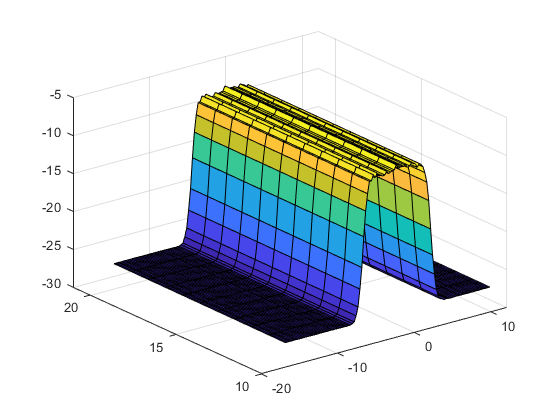

f5 = figure();
surf(X2,Y2,Z2);
set(gcf, "Visible", "on");

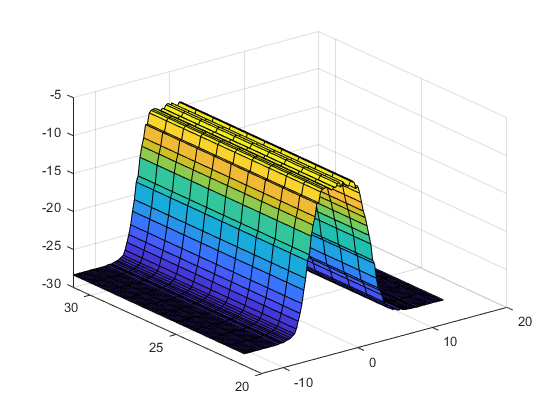

f6 = figure();
surf(X3,Y3,Z3);
set(gcf, "Visible", "on");

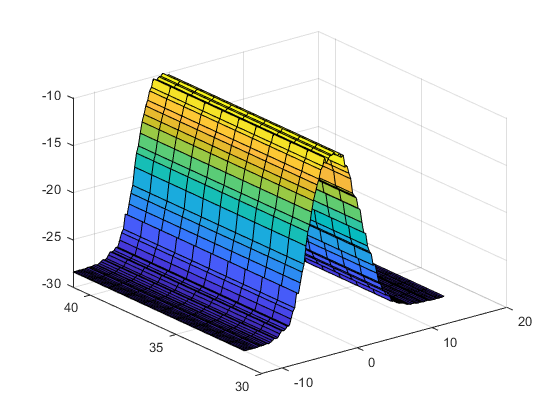

f7 = figure();
surf(X4,Y4,Z4);
set(gcf, "Visible", "on");

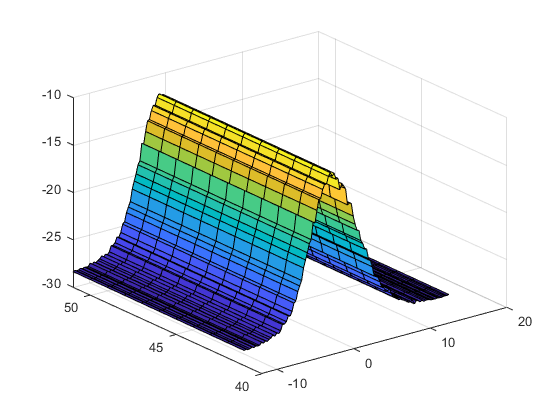

f8 = figure();
surf(X5,Y5,Z5);
set(gcf, "Visible", "on");

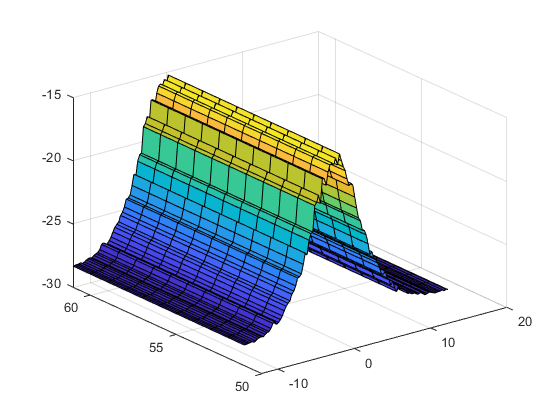

f9 = figure();
surf(X6,Y6,Z6);
set(gcf, "Visible", "on");

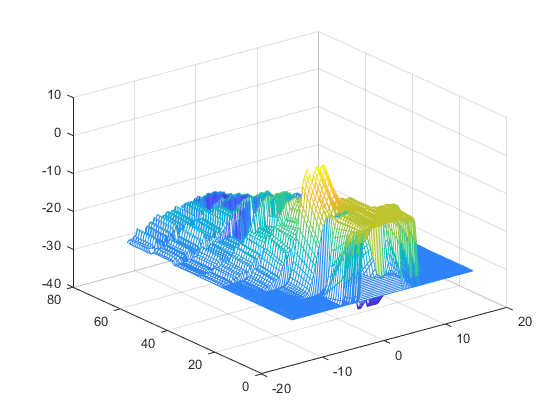

f10 = figure();
%surf(X7,Y7,Z7);
mesh(X1,Y1,Z);
set(gcf, "Visible", "on");

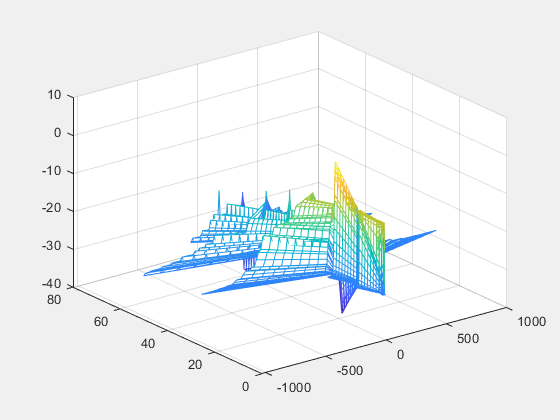

f11 = figure();
%surf(X8,Y8,Z8);
set(gcf, "Visible", "on");
mesh(X,Y,Z);

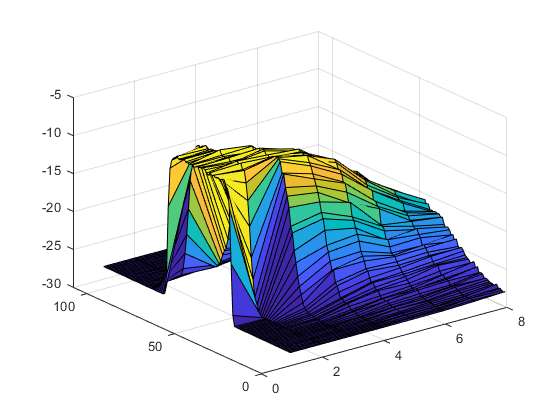

f12 = figure();
surf(U_z);
set(gcf, "Visible", "on");

%plot3(X,Y,Z);



